# Task 3

Load the image and show it.

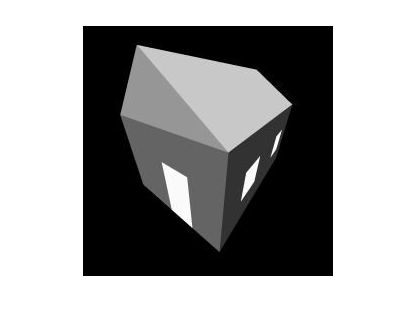

house = imread("../left.jpg");
figure;imshow(house);

Detect the edges in the house

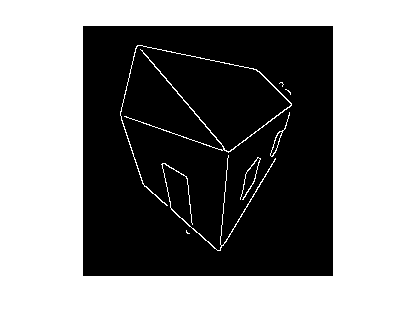

house = edge(house,"canny");
figure;imshow(house);

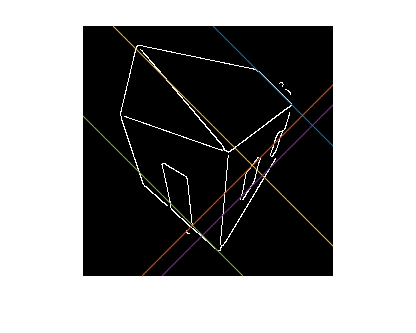

diagonal_len = sqrt(size(house,1)^2+size(house,2)^2);
phi_max = diagonal_len;
theta_max = pi;
n = 100;
[accum_array,phis,thetas,votes] = hough(house,n,theta_max,phi_max,10);
figure;imshow(house);
hold on
for i = 1:numel(phis)
    %x = 0:size(house,2);
    y = @(x)(x.*sin(thetas(i))+phis(i))./cos(thetas(i));
    fplot(y);
end

It seems to find some edges although some are missing, this could likely be improved by lowering the threshold, and just keeping the top lines. It's quite fast for this simple of an image, since the complexity is O(n*n_theta*n_phi) it grows quickly when you want more detail. The precision is also pretty good.

function [accum_array,phis_out,thetas_out,votes]= hough(img,n,theta_max,phi_max,threshold)
    % Generate valid values
    thetas = 0:theta_max/n:theta_max;
    thetas = thetas(1:n);
    % Allow pluss minus phis
    phis = -phi_max:2*phi_max/n:(phi_max);
    phis = phis(1:n);
    cos_thetas = cos(thetas);
    sin_thetas = sin(thetas);
    accum_array = zeros([n,n]);
    % Find all points that are non null, these are edge points
    [e_1,e_2] = find(img ~= 0);
    for index = 1:numel(e_1)
        angle_grades = e_2(index).*sin_thetas-e_1(index).*cos_thetas;
        best = struct('angle',0,'offset',0,'dist',inf);

        for j = 1:numel(phis)
            %   angle_grade = [0.12,.0123,.1235,.532,.009]
            %   phis = [.2,.5,.1,.5]
            for k = 1:numel(angle_grades)
                % Compute "distance", the remainder to 0
                dist = angle_grades(k)+phis(j);
                if abs(dist) < best.dist
                    % New closest to 0
                    % Store the best angle and offset
                    best.angle = k;
                    best.offset = j;
                    best.dist = abs(dist);
                end
            end
        end
        accum_array(best.angle,best.offset) = accum_array(best.angle,best.offset)+1;
    end
    flattend = accum_array(:);
    [flattend_sorted,~] = sort(flattend,"descend");
    phis_out = [];
    thetas_out = [];
    votes = [];
    counter = 1;
    while flattend_sorted(counter) > threshold
        [theta,phi] = find(accum_array == flattend_sorted(counter));
        for index = 1:numel(theta)
            votes = [votes; accum_array(theta(index),phi(index))];
            thetas_out = [thetas_out;thetas(theta(index))];
            phis_out = [phis_out; phis(phi(index))];
        end
        counter=counter+1;
    end
end